# Atividade 03

## Processamento de Sinais

O arquivo Data03.csv contém a resposta de um sensor y(t) obtida durante 2 s com amostragem de 1 ms. A primeira coluna indica o tempo t em s, enquanto que a segunda coluna contém os valores de y(t).

### Parte A: 

dados = readtable("data/Data03.csv");
dados.Properties.VariableNames = {'t', 'y'}

dados = 2001×2 table
      t           y     
    _____    ___________

        0              0
    0.001        0.58779
    0.002        0.95105
    0.003        0.95107
    0.004        0.58778
    0.005     1.2245e-16
    0.006       -0.58776
    0.007        -0.9511
    0.008         -0.951
    0.009       -0.58783
     0.01    -2.4503e-16
    0.011        0.58786
    0.012        0.95092
    0.013        0.95122
    0.014        0.58767
    0.015     3.6706e-16


#### A.1 - Gráfico

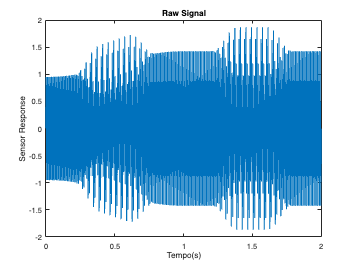

plot(dados.t, dados.y);
title('Raw Signal');
xlabel('Tempo(s)'), ylabel('Sensor Response');

#### A.2 - Valor Médio e RMS

RMS = rms(dados.y)

RMS = 0.7939

media = mean(dados.y)

media = -4.0658e-05

## Parte B:

dt = 1e-3;             % dt do sinal (entre amostragens)
M  = height(dados.y);  % Número de pontos coletados
df = 1/(M * dt)        % df do sinal

df = 0.4998

f  = 0 : df : (M-1)*df % Gera vetor frequencia que o sinal reside

f =          0    0.4998    0.9995    1.4993    1.9990    2.4988    2.9985    3.4983    3.9980    4.4978    4.9975    5.4973    5.9970    6.4968    6.9965    7.4963    7.9960    8.4958    8.9955    9.4953    9.9950   10.4948   10.9945   11.4943   11.9940   12.4938   12.9935   13.4933   13.9930   14.4928   14.9925   15.4923   15.9920   16.4918   16.9915   17.4913   17.9910   18.4908   18.9905   19.4903   19.9900   20.4898   20.9895   21.4893   21.9890   22.4888   22.9885   23.4883   23.9880   24.4878



fourier = fft(dados.y, M); % Calculo de FFT

mag = abs(fourier);               % Calculo de Magnitude por frequência
pha = angle(fourier);             % Calculo do phase shift
pow = (fourier .* conj(fourier)); % Calculo de Espectro de Potência

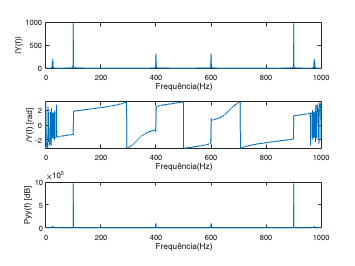

subplot(3, 1, 1);
plot(f, mag);
xlabel('Frequência(Hz)'), ylabel('|Y(f)|');

subplot(3, 1, 2);
plot(f, pha);
xlabel('Frequência(Hz)'), ylabel('/Y(f) [rad]');

subplot(3, 1, 3);
plot(f, pow);
xlabel('Frequência(Hz)'), ylabel('Pyy(f) [dB]');

## Parte C: Análise Spectral

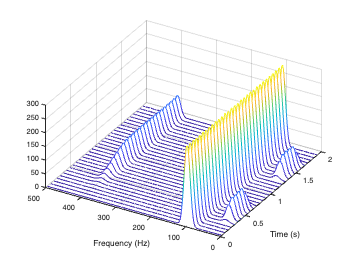

clf;
[s, f, t] = spectrogram(dados.y, 64, 1, M, 1/dt);
waterplot(s, f, t)

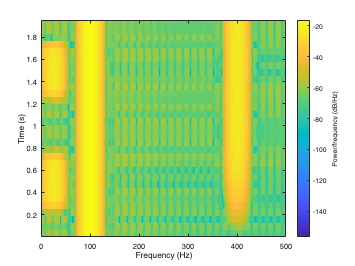

spectrogram(dados.y, 64, 1, M, 1/dt)

## Parte D: Reconstrução

[max_mag, index] = maxk(mag, 50);

freq_1 = f(47)

freq_1 = 22.9885

freq_2 = f(index(1))

freq_2 = 99.9500

freq_3 = f(index(3))

freq_3 = 399.8001


mag_1 = 200 .* (2/M)

mag_1 = 0.1999

mag_2 = max_mag(1).* (2/M)

mag_2 = 0.9834

mag_3 = max_mag(3).* (2/M)

mag_3 = 0.3161


shift_1 = pha(f == freq_1)

shift_1 = -1.5006

shift_2 = pha(f == freq_2)

shift_2 = -1.2569

shift_3 = pha(f == freq_3)

shift_3 = -0.0121

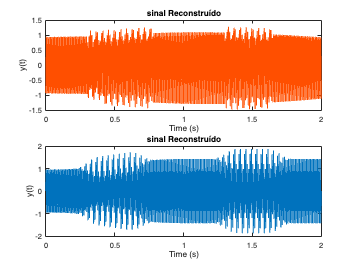


time = 0 : dt : 2;

seno_1 = ((time<0.78 & time > 0.3) + (time > 1.3 & time < 1.65)) .* mag_1 .* sin(freq_1 .* 2 .* pi .* time + shift_1);
seno_2 = mag_2 .* sin(freq_2 .* 2 .* pi .* time + shift_2);
seno_3 = (time > 0.4) .* mag_3 .* sin(freq_3 .* 2 .* pi .* time + shift_3);

subplot(2, 1, 1);
plot(dados.t, seno_3 + seno_2 + seno_1,Color='#FF4F00')
title('sinal Reconstruído');
xlabel('Time (s)'), ylabel('y(t)');

subplot(2, 1, 2);
plot(dados.t, dados.y);
title('sinal Reconstruído');
xlabel('Time (s)'), ylabel('y(t)');

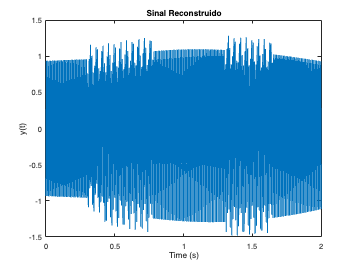

clf;
plot(time, seno_3 + seno_2 + seno_1);
title('Sinal Reconstruido');
xlabel('Time (s)'), ylabel('y(t)');